% Question 1:

% a)
% Définir la valeur de x0 et la dérivée exacte
x0 = 1;
der_exact = -exp(-x0);  % Valeur exacte de la dérivée de exp(-x) en x0

% Initialisation des tableaux pour stocker les valeurs de h et des erreurs
h_values = zeros(1, 18);   % Pour stocker les valeurs de h
error_values = zeros(1, 18); % Pour stocker les erreurs

% Boucle pour les 18 valeurs de h = 10^(-i), i = 1, 2, ..., 18
for i = 1:18
    h = 10^(-i);           
    h_values(i) = h;
    
    % Points x1 et x2 autour de x0
    x1 = x0 + h;          
    x2 = x0 + 2*h;       
    
    % Approximation de la dérivée avec la formule donnée
    f_prime_approx = (-3*exp(-x0) + 4*exp(-x1) - exp(-x2)) / (2*h);
    
    % Calcul de l'erreur relative absolue
    erreur_relative = abs((f_prime_approx - der_exact) / der_exact);
    error_values(i) = erreur_relative;
end

% Graphique loglog de l'erreur relative en fonction de h:
figure;
loglog(h_values, error_values, '-o', 'MarkerSize', 5); 
xlabel('h');                      
ylabel('Erreur relative absolue'); 
title('Erreur relative absolue en fonction de h');  
grid on;    


% b)
k = 5;  % h = 10^-5 minimise l'erreur
h_around_k = h_values(k-2:k+2);  % 5 valeurs centrées autour de h(k)
e_around_k = error_values(k-2:k+2);  % Erreurs correspondantes

% Calculer les log(h) et log(e)
log_h = log(h_around_k);
log_e = log(e_around_k);

% On ajust e un polynôme de degré 4 aux 5 points (log(h), log(e))
coeffs_tilde = polyfit(log_h, log_e, 4);

% On dérive le polynôme pour trouver les points critiques
p_prime_tilde = polyder(coeffs_tilde);
critical_points_log_h_tilde = roots(p_prime_tilde);

% On converti log(h_tilde_opt) en h_tilde_opt pour les racines réelles
h_tilde_opt_candidates = exp(critical_points_log_h_tilde);

% On évalue le polynôme pour ces valeurs de h_tilde_opt candidates
log_e_candidates_tilde = polyval(coeffs_tilde, critical_points_log_h_tilde);

% On identifie la racine qui minimise l'erreur
[~, idx_min_tilde] = min(log_e_candidates_tilde);

% Correspondance avec la meilleure valeur de h_tilde_opt
h_tilde_opt_log = critical_points_log_h_tilde(2);
h_tilde_opt = exp(h_tilde_opt_log); % On revient à l'échelle linéaire

% Recalcule des points x1 et x2 avec h_tilde_opt
x1_tilde = x0 + h_tilde_opt;          
x2_tilde = x0 + 2*h_tilde_opt;        

% Calcule de la valeur de la dérivée approximative pour h_tilde_opt et de l'erreur relative associée
valeur_h_tilde = (-3*exp(-x0) + 4*exp(-x1_tilde) - exp(-x2_tilde)) / (2*h_tilde_opt);
erreur_rel_h_tilde = abs((valeur_h_tilde - der_exact) / der_exact);

% On affiche la valeur de h_tilde_opt et son erreur associée:
disp(['h_tilde_opt = ', num2str(h_tilde_opt)]);

h_tilde_opt = 5.5971e-06


disp(['erreur_rel_h_tilde = ', num2str(erreur_rel_h_tilde)]);

erreur_rel_h_tilde = 2.8088e-11




% On determine l'erreur associee a h_opt de la question 2:
h_opt = 1.2e-5;

% On recalcule les points x1 et x2 avec h_opt
x1_tilde = x0 + h_opt;          
x2_tilde = x0 + 2*h_opt;       

valeur_h = (-3*exp(-x0) + 4*exp(-x1_tilde) - exp(-x2_tilde)) / (2*h_opt);
erreur_rel_h = abs((valeur_h - der_exact) / der_exact);

% On affiche la valeur de h_tilde_opt et son erreur associée:
disp(['h_opt theorique = ', num2str(h_opt)]);

h_opt theorique = 1.2e-05


disp(['erreur associee a h_opt theorique = ', num2str(erreur_rel_h)]);

erreur associee a h_opt theorique = 5.652e-11


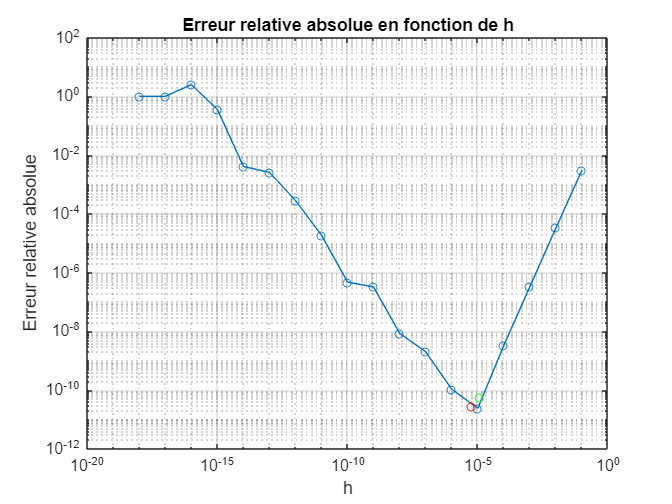


hold on; 
loglog(h_tilde_opt, erreur_rel_h_tilde , 'ro', 'MarkerSize', 5, 'DisplayName', 'h_{\tilde{opt}}'); % Marqueur rouge
loglog(h_opt, erreur_rel_h, 'go', 'MarkerSize', 5, 'DisplayName', 'h_{opt}'); % Marqueur vert
hold off; 

c) 

On voit que l'erreur relative associee a h_tilde_opt est inferieure a celle qu'on avait determine a la question 2 avec la formule (1). Toutefois on peut noter que l'erreur theorique qu'on avait determiner dans la premiere partie est du meme ordre que la reponse en pratique.



% Question 2:
format compact; format short e;

% a) Richardson : pour f'(1) partant de h = 0,1

% Paramètres
x0 = 1;  
h = 0.1 ./ 2.^(0:5)'; 

N = zeros(6,6);  

% Dérivée exacte de f à x0 = 1
n_exact = -exp(-1);

% Calcul de la première colonne avec la formule donnée
N(:,1) = (-3*exp(-x0) + 4*exp(-(x0 + h)) - exp(-(x0 + 2*h))) ./ (2*h);

% On applique l'extrapolation de Richardson pour les autres colonnes
for j = 2:6
    N(j:6,j) = N(j:6,j-1) + (N(j:6,j-1) - N(j-1:5,j-1)) / (4^(j-1) - 1);
end

% Calcul des erreurs absolues
en = abs(N - n_exact); 

% Affichage des tableaux N
disp('Tableau N :');

Tableau N :


disp(N);

  -3.6674e-01            0            0            0            0            0
  -3.6758e-01  -3.6787e-01            0            0            0            0
  -3.6780e-01  -3.6788e-01  -3.6788e-01            0            0            0
  -3.6786e-01  -3.6788e-01  -3.6788e-01  -3.6788e-01            0            0
  -3.6787e-01  -3.6788e-01  -3.6788e-01  -3.6788e-01  -3.6788e-01            0
  -3.6788e-01  -3.6788e-01  -3.6788e-01  -3.6788e-01  -3.6788e-01  -3.6788e-01


disp('Tableau des erreurs en :');

Tableau des erreurs en :


disp(en);

   1.1384e-03   3.6788e-01   3.6788e-01   3.6788e-01   3.6788e-01   3.6788e-01
   2.9533e-04   1.4299e-05   3.6788e-01   3.6788e-01   3.6788e-01   3.6788e-01
   7.5221e-05   1.8504e-06   1.0205e-06   3.6788e-01   3.6788e-01   3.6788e-01
   1.8982e-05   2.3536e-07   1.2769e-07   1.1352e-07   3.6788e-01   3.6788e-01
   4.7677e-06   2.9677e-08   1.5966e-08   1.4192e-08   1.3803e-08   3.6788e-01
   1.1947e-06   3.7260e-09   1.9958e-09   1.7741e-09   1.7254e-09   1.7136e-09



% Vérification des ordres de précision
disp('Vérification des ordres de précision :');

Vérification des ordres de précision :



for i = 1:5  %  Les 5 premières colonnes
    if i < 6 && all(en(2:end, i) ~= 0)
        ratios = en(1:end-1, i) ./ en(2:end, i);  % Calcule du rapport
        
        %  l'indice de départ pour les ratios à afficher, sinon on a des
        %  ratios inutiles qui sont fait
        startIndex = i;

        % Affichage des ratios:
        fprintf('%dème colonne : Ratios = ', i);
        disp(ratios(startIndex:end));
    else
        fprintf('%dème colonne : Erreurs nulles ou inexistantes.\n', i);
    end
end

1ème colonne : Ratios = 

   3.8548e+00
   3.9262e+00
   3.9628e+00
   3.9813e+00
   3.9906e+00


2ème colonne : Ratios = 

   7.7275e+00
   7.8619e+00
   7.9305e+00
   7.9651e+00


3ème colonne : Ratios = 

   7.9917e+00
   7.9979e+00
   7.9994e+00


4ème colonne : Ratios = 

   7.9988e+00
   7.9996e+00


5ème colonne : Ratios = 

   7.9996e+00


On peut noter que les erreures absolues pour les colonnes 1 et 2 respectent la theorie avec des ordres de precision pratique de O(h^2) et O(h^3). Cependant, a partir de la colonne 2 jusqu'a la 5 eme colonne on ne depasse pas l'odre de precision O(h^3) alors que dans la theorie on devrait arriver a un ordre de convergence pour N6 de grandeur O(h^7). . 